# MECH 6323 - Final Project

Author: Jonas Wagner

Date: 2022-05-13

clc
clear
close all
sympref('MatrixWithSquareBrackets',true);
sympref('FloatingPointOutput',true);

## Nominal Plant Definition

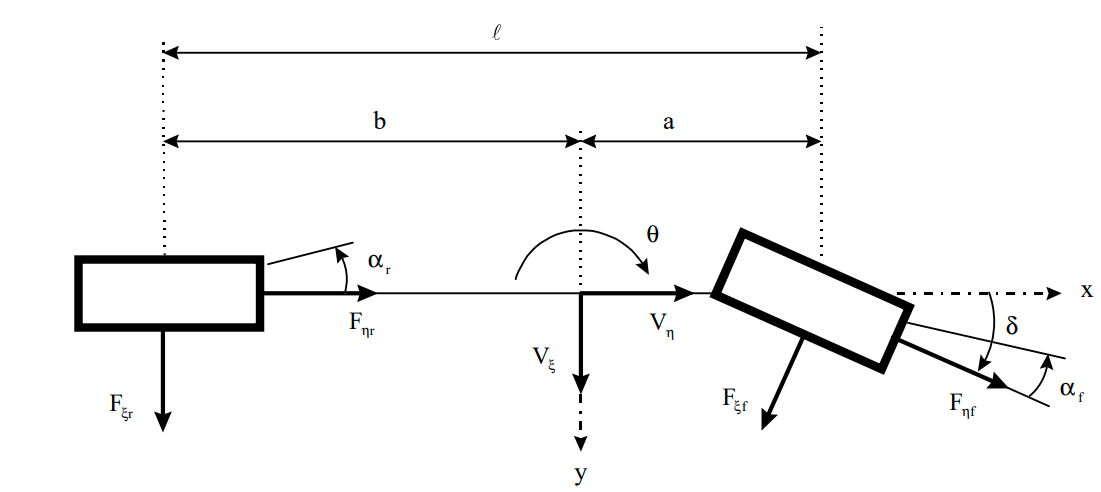


$$x = [\dot{\theta}, V_\zeta, V_\eta, x, y, \theta]^T
$$



$$u = [\delta, F_{\eta f}, F_{\eta r}, F_{\zeta f}, F_{\zeta r}]^T$$


N = 6;
x_sym = [
    sym('theta_dot')
    sym('V_zeta')
    sym('V_eta')
    sym('x')
    sym('y')
    sym('theta')
]

$$x\_sym = \left[\begin{array}{c} \dot{\theta }\\ V_{\zeta }\\ V_{\eta }\\ x\\ y\\ \theta \end{array}\right]$$

u_sym = [
    sym('delta')
    sym('F_zeta_f')
    sym('F_zeta_r')
    sym('F_eta_f')
    sym('F_eta_r')
]

$$u\_sym = \left[\begin{array}{c} \delta \\ F_{\zeta ,f}\\ F_{\zeta ,r}\\ F_{\eta ,f}\\ F_{\eta ,r} \end{array}\right]$$

params_sym = {};
params_sym.a = sym('a');
params_sym.b = sym('b');
params_sym.m = sym('m');
params_sym.I = sym('I');
params_sym.alpha_f = sym('alpha_f');
params_sym.alpha_r = sym('alpha_r');

 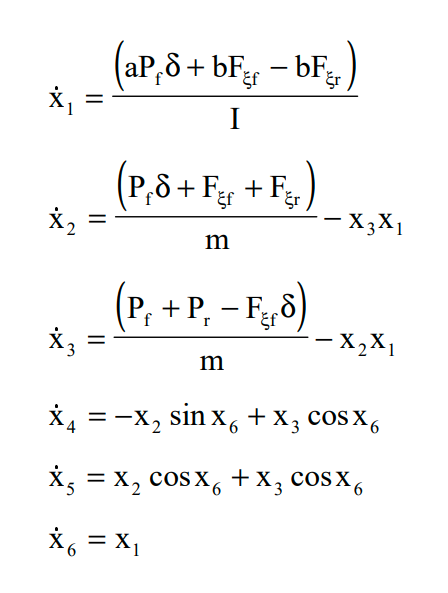       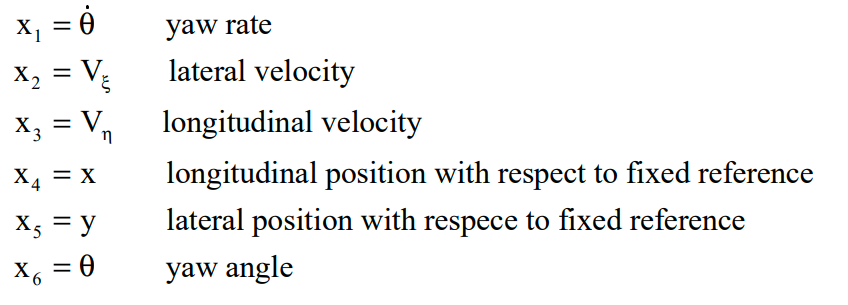

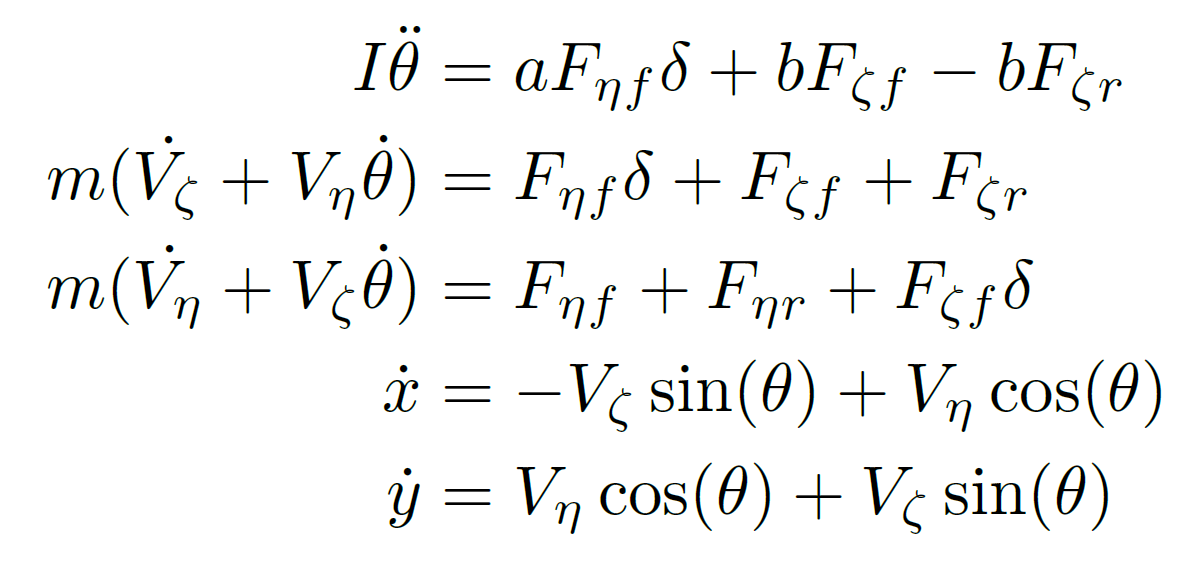

Note that $F_{\eta f} = P_f$ and $F_{\eta r} = P_r$ when in an ideal plant model... effected by slipage

bike_nonlin_dot = @(x, u, params) [
    (params.a*u(2)*u(1) + params.b*u(4) - params.b*u(5))/params.I;
    (u(2)*u(1) + u(4) + u(5))/params.m - x(3)*x(1);
    (u(2) + u(3) - u(5)*u(1))/params.m - x(2)*x(1);
    -x(2)*sin(x(6)) + x(3)*cos(x(6));
    x(2)*cos(x(6)) + x(3)*cos(x(6));
    x(1);
];
bike_nonlin_dot_sym = bike_nonlin_dot(x_sym, u_sym, params_sym)

$$bike\_nonlin\_dot\_sym = \left[\begin{array}{c} \frac{F_{\eta ,f}\,b-F_{\eta ,r}\,b+F_{\zeta ,f}\,a\,\delta }{\text{I}}\\ \frac{F_{\eta ,f}+F_{\eta ,r}+F_{\zeta ,f}\,\delta }{m}-V_{\eta }\,\dot{\theta }\\ \frac{F_{\zeta ,f}+F_{\zeta ,r}-F_{\eta ,r}\,\delta }{m}-V_{\zeta }\,\dot{\theta }\\ V_{\eta }\,\cos\left(\theta \right)-V_{\zeta }\,\sin\left(\theta \right)\\ V_{\eta }\,\cos\left(\theta \right)+V_{\zeta }\,\cos\left(\theta \right)\\ \dot{\theta } \end{array}\right]$$

eq_bike_latex = ['$\dot{x} = ', latex(bike_nonlin_dot_sym),'$'];

#### Nominal Model

params.a = 1.228;
params.b = 1.5618;
params.m = 1500;
params.I = 12;
params.alpha_f = 0.1;
params.alpha_r = 0.1;
params.c = 0.1;

bike_nonlin_dot_nom = bike_nonlin_dot(x_sym, u_sym, params)

$$bike\_nonlin\_dot\_nom = \left[\begin{array}{c} 0.1302\,F_{\eta ,f}-0.1302\,F_{\eta ,r}+0.1023\,F_{\zeta ,f}\,\delta \\ 6.6667e-04\,F_{\eta ,f}+6.6667e-04\,F_{\eta ,r}+6.6667e-04\,F_{\zeta ,f}\,\delta -V_{\eta }\,\dot{\theta }\\ 6.6667e-04\,F_{\zeta ,f}+6.6667e-04\,F_{\zeta ,r}-6.6667e-04\,F_{\eta ,r}\,\delta -V_{\zeta }\,\dot{\theta }\\ V_{\eta }\,\cos\left(\theta \right)-V_{\zeta }\,\sin\left(\theta \right)\\ V_{\eta }\,\cos\left(\theta \right)+V_{\zeta }\,\cos\left(\theta \right)\\ \dot{\theta } \end{array}\right]$$

## Linearized Model

This is an unrealistic thing to do outside of single time-steps

A_sym = jacobian(bike_nonlin_dot(x_sym,u_sym,params_sym),x_sym)

$$A\_sym = \left[\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ -V_{\eta } & 0 & -\dot{\theta } & 0 & 0 & 0\\ -V_{\zeta } & -\dot{\theta } & 0 & 0 & 0 & 0\\ 0 & -\sin\left(\theta \right) & \cos\left(\theta \right) & 0 & 0 & -V_{\zeta }\,\cos\left(\theta \right)-V_{\eta }\,\sin\left(\theta \right)\\ 0 & \cos\left(\theta \right) & \cos\left(\theta \right) & 0 & 0 & -V_{\eta }\,\sin\left(\theta \right)-V_{\zeta }\,\sin\left(\theta \right)\\ 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right]$$

B_sym = jacobian(bike_nonlin_dot(x_sym,u_sym,params_sym),u_sym)

$$B\_sym = \left[\begin{array}{ccccc} \frac{F_{\zeta ,f}\,a}{\text{I}} & \frac{a\,\delta }{\text{I}} & 0 & \frac{b}{\text{I}} & -\frac{b}{\text{I}}\\ \frac{F_{\zeta ,f}}{m} & \frac{\delta }{m} & 0 & \frac{1}{m} & \frac{1}{m}\\ -\frac{F_{\eta ,r}}{m} & \frac{1}{m} & \frac{1}{m} & 0 & -\frac{\delta }{m}\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right]$$

A = matlabFunction(A_sym, 'Vars', {x_sym, u_sym, sym('a'), sym('b'), sym('m'), sym('I')});
B = matlabFunction(B_sym, 'Vars', {x_sym, u_sym, sym('a'), sym('b'), sym('m'), sym('I')});

## Uncertain Plant Dynamics and Disturbances

All the calculations here are dependent on the nominal dynamics.

params

params = struct with fields:
          a: 1.2280
          b: 1.5618
          m: 1500
          I: 12
    alpha_f: 0.1000
    alpha_r: 0.1000
          c: 0.1000


### Physical Disturbances

### Tire Slipage

We have options to model the tire slipage better (actually what alphas are used for) but they are highly nonlinear and are also highly dependent on $m$ so it is very difficult to model acurately. Instead we will model tire with a disturbance input and have it be modeled a disturbance within the $F_\zeta$ for each tire. For simplicity we will make it a parameter that is really only dependent on the unchanging parameters $a$, $b$, $\alpha$ and $m$ since these are what effect this in real life.


$$F_{\zeta f} = W_{\zeta f} \cdot z_{\zeta f}, \ z_{\zeta f} \in [-1,1]$$


W_zeta_f = 1e3 * (params.a / params.b) * params.alpha_f / params.m

W_zeta_f = 0.0524


$$F_{\zeta r} = W_{\zeta r} \cdot z_{\zeta r}, \ z_{\zeta r} \in [-1,1]$$


W_zeta_r = 1e3 * (params.b / params.a) * params.alpha_r / params.m

W_zeta_r = 0.0848

#### Wind Resistance

Although the NOVA vehcile will be going slow enough that wind negligence is negligable, including it seemed worth while. The disturbance itself is a multiplicative noise dependent on the forward velocity. Since the rear wheels will always be aligned with the direction of the vehicle we will take the force to act as a force counter to any foward force done by the tires (which in this front-wheel configuration this is 0). 

This weighting disturbance is directly proportional to the longitudinal velocity:


$$F_{\eta r} = W_{\eta_r} \cdot V_{\eta} \cdot z_{\eta}, \ z_{\eta} \in [0, 1]$$


W_eta_r = params.c;

### Uncertain/Nonlinear Actuators

#### Steering and Forward Force Delays

Both a human and autonomous driver takes a while to react, while both the steering mechanism and engine/drivetrain also contain delays. We also assume it is only a front-wheel drive vehicle, so only the front wheel will be providing force to move the vehicle.

tau_driver = 0.1;
tau_drivetrain = 2;
W_delta = (1/pi) * zpk([], 1/tau_driver, 1)

W_delta =
 
  0.31831
  -------
  (s-10)
 
Continuous-time zero/pole/gain model.



W_eta_f = 1e-3 * (params.a / params.b) * params.m * zpk([],[1/tau_driver, 1/tau_drivetrain],1)

W_eta_f =
 
      1.1794
  --------------
  (s-10) (s-0.5)
 
Continuous-time zero/pole/gain model.



### Sensors and Measurement Noise

#### Gyroscope

The gyroscope will measure the rotational velocity of the system which will allow an observer to measure the current state with fairly high acuracy if you average it (which isn't really that useful when you would need to integrate or differentiate them) but will be noisy at higher frequencies if sampled often.

The gyro measurment output will therefore be:


$$y_{gyro} = \dot{\theta} + W_{gyro} \cdot z_{gyro}, \ z_{gyro} \in [-1,1]$$


z_0_gyro = 5;
tau_gyro = 0.01;
bw_gyro = 500;
W_gyro = zpk(1/tau_gyro / bw_gyro, 1/tau_gyro * bw_gyro, z_0_gyro)

W_gyro =
 
  5 (s-0.2)
  ---------
  (s-5e04)
 
Continuous-time zero/pole/gain model.



#### Spedometer

The spedometer is just a measurement directly of the Longitudinal Velocity, $V_\eta$, and will have a measurement noise that is only really aparent at higher frequencies.

The gyro measurment output will therefore be:


$$y_{sped} = V_{\eta} + W_{sped} \cdot z_{sped}, \ z_{sped} \in [-1,1]$$


z_0_sped = 2;
tau_sped = 1;
bw_sped = 10;
W_sped = zpk(1/tau_sped / bw_sped, 1/tau_sped * bw_sped, z_0_sped)

W_sped =
 
  2 (s-0.1)
  ---------
   (s-10)
 
Continuous-time zero/pole/gain model.



#### GPS

The GPS system will be used to calculate the global position over a longer period of time for the system. Similar to the Gyroscope, the GPS will have error at low ends and isn't going to ever truely be acurate over-time in a real-world situation by itself without other information used by a Kalmen Filter or similar in congunction with other sensors (such as Lidar) and orther localization techniques (which is a big part of what NOVA has been working on this semester). We will assume that the sensor error output from the gps will be white noise that is filtered out mostly (becouse of the way it is averaged and sampled so higher frequencies become less important) except for a region.


$$y_{gps, x} = x + W_{gps} \cdot z_{gps}, \ z_{gps} \in [-1,1]$$



$$y_{gps, y} = y + W_{gps} \cdot z_{gps}, \ z_{gps} \in [-1,1]$$


z_0_gps = 10;
tau_gps = 10;
bw_gps  = 1000;
W_gps = tf(bw_gps/tau_gps, [1 bw_gps/tau_gps (1/tau_gps)^2])

W_gps =
 
         100
  ------------------
  s^2 + 100 s + 0.01
 
Continuous-time transfer function.



### Parameteric Uncertainty

Parameteric Uncertainty essentially just assumes deviations from potential modeling issues. For the current analysis this is ignored in order to focus on actuator uncertainty.

Actually, I ended up deciding to do just that... but just with a more standard thing.

params_u = params;
a_u = ureal('a', params.a, 'Percentage', 1);
b_u = ureal('b', params.b, 'Percentage', 1);
m_u = ureal('m', params.m, 'Percentage', 25);
I_u = ureal('I', params.I, 'Percentage', 25);
a_ulpha_f = ureal('alpha_f', params.alpha_f, 'Percentage', 25);
a_ulpha_r = ureal('alpha_r', params.alpha_r, 'Percentage', 25);
params_u.c = ureal('c', params.c, 'Percentage', 25);

## Plant Model and Controller Design

#### Nominal Plant

A_nom = @(x_0, u_0) A(x_0, u_0, params.a, params.b, params.m, params.I);
B_nom = @(x_0, u_0) B(x_0, u_0, params.a, params.b, params.m, params.I);

x_0 = [0; 5; 0; 0; 0; 0];
u_0 = [0; 10; 0; 0; 0];
r_0 = [0; 5; 0; 0; 0; pi/4];
R = @(t) r_0 + r_0(2)/sqrt(2) * [0;0;0;t;t;0];

sys_nom = ss(A_nom(x_0,u_0), B_nom(x_0,u_0), eye(N), 0)

sys_nom =
 
  A = 
       x1  x2  x3  x4  x5  x6
   x1   0   0   0   0   0   0
   x2   0   0   0   0   0   0
   x3  -5   0   0   0   0   0
   x4   0   0   1   0   0  -5
   x5   0   1   1   0   0   0
   x6   1   0   0   0   0   0
 
  B = 
              u1         u2         u3         u4         u5
   x1      1.023          0          0     0.1302    -0.1302
   x2   0.006667          0          0  0.0006667  0.0006667
   x3          0  0.0006667  0.0006667          0          0
   x4          0          0          0          0          0
   x5          0          0          0          0          0
   x6          0          0          0          0          0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   1
 
  D = 
       u1  u2  u3  u4  u5
   y1   0   0   0   0   0
   y2   0   0   0   0   0
   y3   0   0   0   0   0
   

#### Uncertain Plant

A_u = [
    0, 0, 0, 0, 0, 0; 
    -x_0(3), 0, -x_0(1), 0, 0, 0; 
    -x_0(2), -x_0(1), 0, 0, 0, 0; 
    0, -sin(x_0(5)), cos(x_0(5)), 0, 0, - x_0(2)*cos(x_0(5)) - x_0(3)*sin(x_0(5)); 
    0, cos(x_0(5)), cos(x_0(5)), 0, 0, - x_0(3)*sin(x_0(5)) - x_0(2)*sin(x_0(5)); 
    1, 0, 0, 0, 0, 0
];
B_u = [
    (u_0(2)*a_u)/I_u, (a_u*u_0(1))/I_u, 0, b_u/I_u, -b_u/I_u; 
    x_0(1)/m_u, u_0(1)/m_u, 0, 1/m_u, 1/m_u; 
    -x_0(5)/m_u, 1/m_u, 1/m_u, 0, -u_0(1)/m_u; 
    0, 0, 0, 0, 0; 
    0, 0, 0, 0, 0; 
    0, 0, 0, 0, 0
];
C_u = eye(size(A_u));%[diag([1, 1, 0, 1, 1]),zeros(5,1)];%
D_u = zeros(size(C_u,1),size(B_u,2));
sys_plant_u = uss(A_u,B_u,C_u,D_u);
sys_plant_u_local = sys_plant_u(1,1);

## Simulink Modeling

### Plant Modeling

#### Plant Internal Diagram

The plant internal diagram includes the orignal physical dynamics within a standard LTI system block and all of the weighting functions for the actuators and sensors containing the uncertainty.

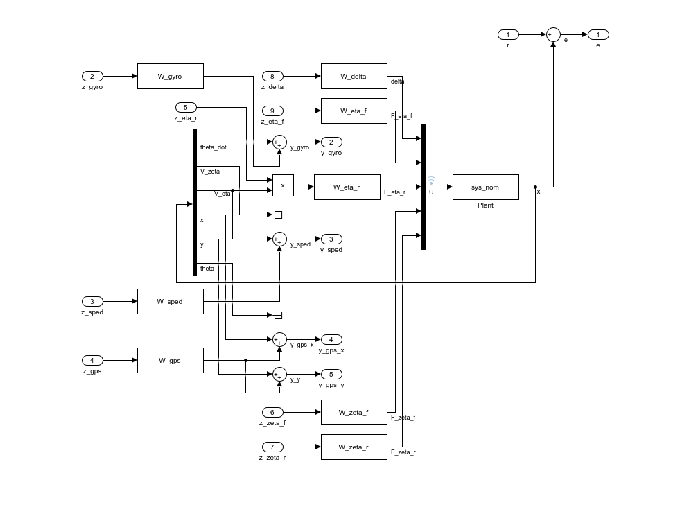

plant_fname = 'plant_bike_lin';
open(plant_fname)
imgname = ['plant_w_act_&_sen', '.png'];
print(['-s', plant_fname,'/Plant'], '-dpng', imgname)
imshow(imgname)

#### plant_bike_lin.slx

The plant is then agrigated within another subsystem block that is structured as a generalized plant model to be used for designing the -controller. 

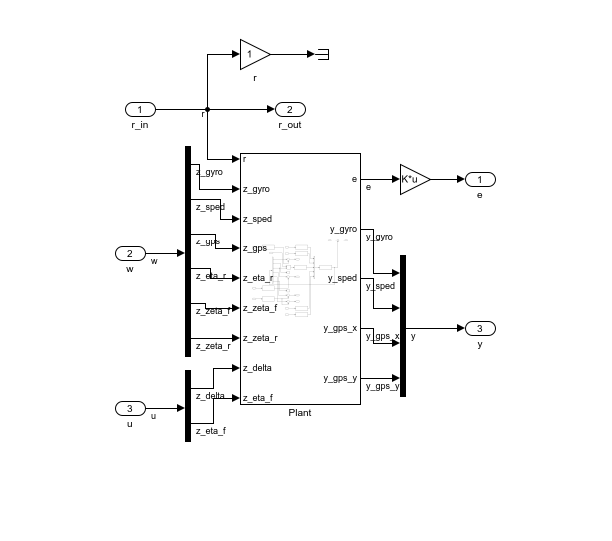

plant_fname = 'plant_bike_lin';
imgname = [plant_fname, '.png'];
print(['-s', plant_fname], '-dpng', imgname)
imshow(imgname)

#### Generalized Linear Plant Model:

mdl = 'sim_hinf_bike';
open(mdl);
clear io
io(1) = linio([mdl,'/r'],1,'input');
io(2) = linio([mdl,'/w'],1,'input');
io(3) = linio([mdl,'/u'],1,'input');
io(4) = linio([mdl,'/Plant'],1,'output');
io(5) = linio([mdl,'/Plant'],2,'output');
io(6) = linio([mdl,'/Plant'],3,'output');
sys_plant = linearize(mdl,io)

sys_plant =
 
  A = 
                 Plant/Intern  Plant/Intern  Plant/Intern  Plant/Intern  Plant/Intern  Plant/Intern  LTI System/I  LTI System/I  LTI System1/  LTI System5/  LTI System6/
   Plant/Intern             0             0             0             0             0             0             0             0        0.6515             0             0
   Plant/Intern             0             0             0             0             0             0             0             0      0.004244             0             0
   Plant/Intern            -5             0             0             0             0             0     0.0007863             0             0             0             0
   Plant/Intern             0             0             1             0             0            -5             0             0             0             0             0
   Plant/Intern             0             1             1             0             0             0             0             0  

## H-infty Controller Design

The rank of our controllability is needed to ensure that the system is actually controllable.

ctr_mat = ctrb(sys_plant);
ctrb_rank = rank(ctr_mat)

ctrb_rank = 1

whoose result bears terrible news. 

The rank being 1 unfortunently means that the entire project is built on false assumptions, leading to a complete failure to even have a controllable (let alone robust) system. Looking back, the assumptions made where the lateral force on the side of the wheel was solely a weighted value dependent on the 

nmeas = 11;
ncont = 9;
[K,CL,GAM,info] = hinfsyn(sys_plant,nmeas,ncont)


K =

     []


CL =

     []



GAM = Inf


info =

     []



Although a pretty terrible conclusion, it is clear that the system being controlled by the linear plant is not able to be controlled with the standard hinfsyn structure.

## Print Out as pdf

fname = matlab.desktop.editor.getActiveFilename;
export(fname, [fname(1:length(fname)-4),'.pdf']); 
%saves the .mlx file to a .pdf in the same directory with the same name